# Data exploration for raw xy files

## PURPOSE

This is code is to calculate general metrics for the xy output from antrax that were merged

## INPUT

clear

% input file information
xyDir = "/Users/lizimai/Insync/zimai.li@evobio.eu/Google Drive/DoctorToBe/01_Projects/ZIM01_Nematode/P2_Tracking/01_Data/cam5";
xyFileinfo = dir(fullfile(xyDir,'xy*.mat'));
xyFilename = (sort({xyFileinfo.name}))';

% create output matrix with experiment information in the xy file names
output = table(xyFilename,'VariableNames',{'Filename'});
splitNames = split(output.Filename, ["_","."]);
output.Treatment = splitNames(:, 2);
output.Number = str2double(splitNames(:, 3));

% data filtering
treatRm = "X"; % treatment to remove
frameKeep = 864000; % frame to keep

## Clean Data

% filter some treatments
outputFiltered = output(output.Treatment~=treatRm,:);

% create empty matrix 
numFile = length(outputFiltered.Filename);
xyMatrix = {};

for i = 1:numFile
    xyMatrix = load(fullfile(xyDir, outputFiltered.Filename(i))).xy(1:frameKeep,:); % load xy matrix
    numAnts = size(xyMatrix, 2)/2;
    assignmentRate = 1 - sum(isnan(xyMatrix),'all')/(size(xyMatrix, 1)*outputFiltered.NumAnts(i)*2);

    % calculate basic statistics   
    outputFiltered.NumAnts(i) = numAnts; % count number of ants
    outputFiltered.AssignmentRate(i) = assignmentRate; % count the assignment rate
end

outputFiltered

outputFiltered = 4×5 table
       Filename       Treatment    Number    NumAnts    AssignmentRate
    ______________    _________    ______    _______    ______________

    {'xy_C_2.mat'}      {'C'}        2          8          0.75175    
    {'xy_C_9.mat'}      {'C'}        9          8          0.91095    
    {'xy_T_1.mat'}      {'T'}        1          8          0.90338    
    {'xy_T_6.mat'}      {'T'}        6          8          0.76118    


## OUTPUT

load("xy_C_2.mat")
xyTrunc = xy(1:864000,:)

h = plot(xyTrunc(:,1), xyTrunc(:,2));
for i = 3:2:15
    x = xyTrunc(:,i);
    y = xyTrunc(:,i+1);
    set(h,'XData',x,'YData',y)    
xlim([0.0050 0.0550])
ylim([0.0050 0.0549])
    drawnow;
    pause(0.1)
end

load("xy_C_2.mat")
xyTrunc = xy(1:864000,:)

xyTrunc =     0.0416    0.0133    0.0416    0.0133    0.0416    0.0133    0.0416    0.0133    0.0416    0.0133    0.0416    0.0133    0.0416    0.0133    0.0416    0.0133
    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133
    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133
    0.0416    0.0132    0.0416    0.0132    0.0416    0.0132    0.0416    0.0132    0.0416    0.0132    0.0416    0.0132    0.0416    0.0132    0.0416    0.0132
    0.0422    0.0136    0.0422    0.0136    0.0385    0.0110    0.0422    0.0136    0.0422    0.0136    0.0422    0.0136    0.0422    0.0136    0.0422    0.0136
    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133    0.0417    0.0133
    0.0417    0.0133    

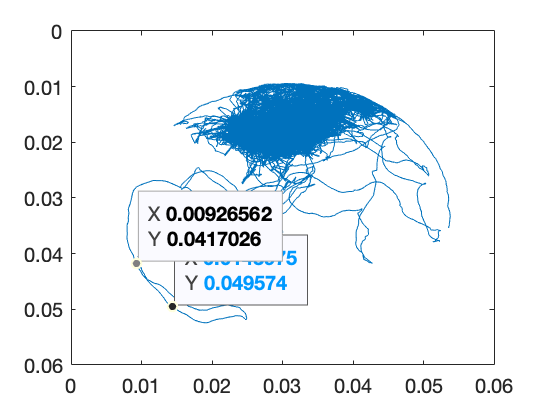


% how to match the colour

for i = 1:2:15
    plot(xyTrunc(:,i), xyTrunc(:,i+1));
    axis ij;
    drawnow;
    pause(0.1)
end